%绘制路径曲线




% 定义参数a和l
a = 0.4;
l = 0.4;

% 定义参数u的范围
u = linspace(0, pi, 1000); % 生成从0到pi的1000个点

% 根据参数方程计算x和y坐标
x = -2*a .* ((l - cos(u)) .* cos(u) +( 1 - l));
y = 2*a .* (l - cos(u)) .* sin(u);

width_of=max(x)-min(x)

width_of = 1.1520

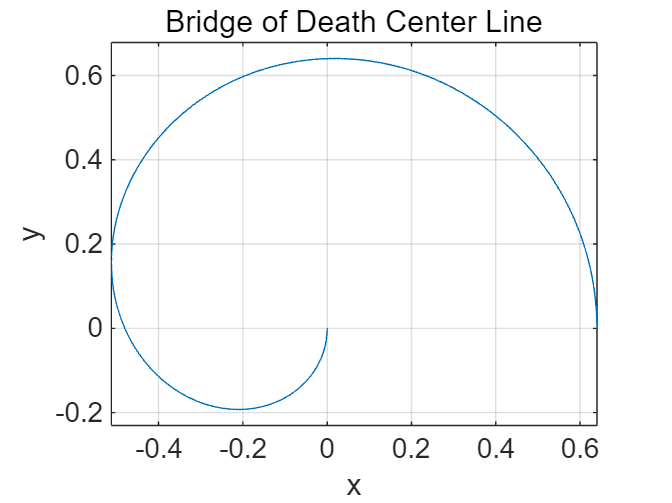

% 绘制曲线
plot(x, y);
axis equal; % 保持x和y轴的刻度一致
grid on;    % 显示网格
title('Bridge of Death Center Line');
xlabel('x');
ylabel('y');

% 定义曲线的参数方程
A = 0.4;
x = @(u) -2 * A * ((0.4 - cos(u)) .* cos(u) + (1 - 0.4));
y = @(u) 2 * A * (0.4 - cos(u)) .* sin(u);

% 定义参数范围
u_min = 0;
u_max = pi;
delta_u = 0.0001; % 步长

% 初始化曲线长度
curve_length = 0;

% 计算曲线长度
u = u_min;
while u < u_max
    % 计算相邻点的坐标
    x1 = x(u);
    y1 = y(u);
    x2 = x(u + delta_u);
    y2 = y(u + delta_u);
    
    % 计算两点之间的距离并累加到曲线长度
    curve_length = curve_length + sqrt((x2 - x1)^2 + (y2 - y1)^2);
    
    % 更新参数值
    u = u + delta_u;
end

u

u = 3.1416